***Wireless Communications EL-GY 6023***

Homework 5 - Tommy Azzino (ta1731)

Problem 2

ks = 0:9;
Pt = zeros(length(ks),1);
alpha_0 = 1; % we know that X_0=0
Pt(1) = 0.4; % P(Y0=1|X0=0);
for k=ks(2:end)
    alpha_0 = (0.04+0.38*alpha_0)/(0.2+0.4*alpha_0);
    Pt(k+1) = (1-sum(Pt(1:(k))))*(0.8-0.4*alpha_0);
end
disp(Pt);

    0.4000
    0.3120
    0.1570
    0.0723
    0.0325
    0.0145
    0.0065
    0.0029
    0.0013
    0.0006



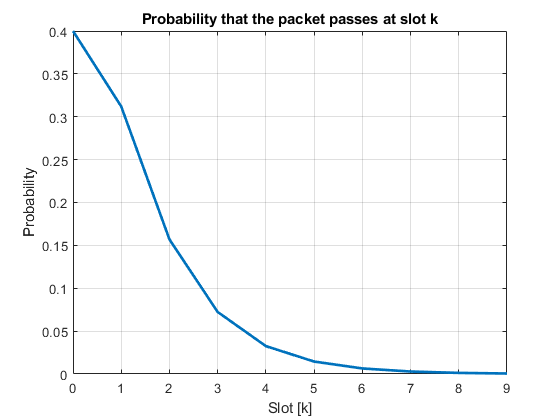

figure;
plot(ks, Pt, "LineWidth",2); grid on;
xlabel("Slot [k]"); ylabel("Probability");
title("Probability that the packet passes at slot k");

disp(sum(Pt));

    0.9995



If I consider more slots the sum of the probability values is 1, as expected. Also, it never exceeds 1, even with a huge number of slots considered.

Problem 6    

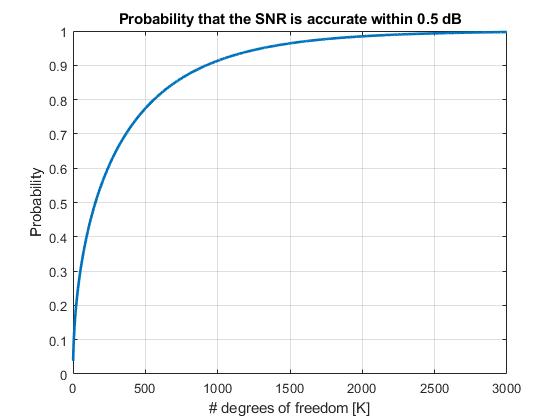

num_ks = 3000;
k = 1:num_ks;
true_avgSnr_db = 3;
true_avgSnr = db2pow(true_avgSnr_db);
target_db = 0.5;
gamma_max = db2pow(true_avgSnr_db+target_db);
gamma_min = db2pow(true_avgSnr_db-target_db);
a = ((gamma_max+1)/(true_avgSnr+1));
b = ((gamma_min+1)/(true_avgSnr+1));
prob = fcdf(a,2*k,2*k) - fcdf(b,2*k,2*k);

figure;
plot(k, prob, "LineWidth",2); grid on;
xlabel("# degrees of freedom [K]");
ylabel("Probability");
title("Probability that the SNR is accurate within 0.5 dB");

As we can see from the figure above, as we increase the number of degrees of freedom (i.e. the number of symbols we use to estimate the SNR), the probability of having an estimation accuracy within 0.5 dB increases

Problem 9

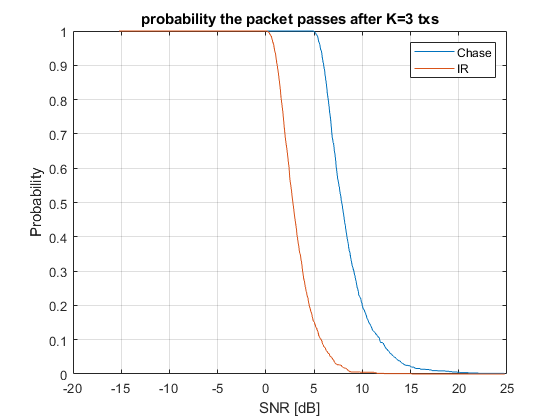

K = 3;
npoints = 1000;
avg_snr = 3;
gammas = exprnd(repmat(avg_snr,[npoints,K]));
gammas_lin = db2pow(gammas);

n_targets = 10000;
gamma_target = linspace(0,300,n_targets);
prob_chase = zeros(n_targets,1);
prob_ir = zeros(n_targets,1);
Rchase = zeros(n_targets,1);
Rir = zeros(n_targets,1);
for i=1:n_targets
    gamma_t = gamma_target(i);
    passed = sum(gammas_lin,2) >= gamma_t;
    prob_chase(i) = sum(passed)/length(passed);
    passed_ir = sum(log2(1+gammas_lin),2)/K >= log2(1+gamma_t); 
    prob_ir(i) = sum(passed_ir)/length(passed_ir);
    Rchase(i) = log2(1+gamma_t)/K;
    Rir(i) = log2(1+gamma_t);
end

figure;
plot(pow2db(gamma_target), prob_chase); grid on; hold on;
plot(pow2db(gamma_target), prob_ir);
legend("Chase", "IR"); xlabel("SNR [dB]"); ylabel("Probability");
title("probability the packet passes after K=3 txs");

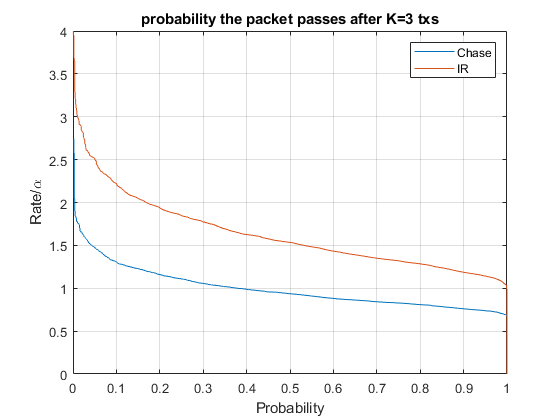

figure;
plot(prob_chase,Rchase); grid on; hold on;
plot(prob_ir, Rir);
legend("Chase", "IR"); ylabel("Rate/\alpha");
xlabel("Probability");
title("probability the packet passes after K=3 txs");
ylim([0 4]); xlim([0 1]);